# Maximizing Solar Panel Output for a Fixed Area

This project will use MATLAB to formulate and solve an optimization problem: Given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

## Break Down the Problem

**In the space below, define the problem statement:**

The problem statement is to solve the optimization problem where given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output. 

**List the requirements, constraints, and success criteria for the project:**

- Requirements: Determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

- Constraints: Area is fixed (2m^2), 0° ≤ θ ≤ 90° and 0.5 ≤ r ≤ 4.

- Success criteria: Find a numerical value for the optimal tilt angle, aspect ratio, and the maximum energy output. Include a visualization of the energy output equation.

**What is your proposed solution?**

Create a MATLAB simulation to model the problem and find the optimal tilt angle and aspect ratio of the solar panel to maximize output. Utilize Optimization Toolbox on MATLAB.

**List the steps you will need to take to achieve your proposed solution:**

- Define the objective function.

- Find the optimal tilt angle and aspect ratio.

- Plot the energy function.

**What challenges do you face in the process of achieving the solution?**

One of the challenges that we faced in the process of achieving the solution was getting familiarized with MATLAB and understanding what each function does for solving the optimization problem. We used the documentation for Problem-Based Optimization Workflow and Onramp course to learn about MATLAB and solve the problem. 

## Task 1: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its tilt angle (theta) and aspect ratio (r): 

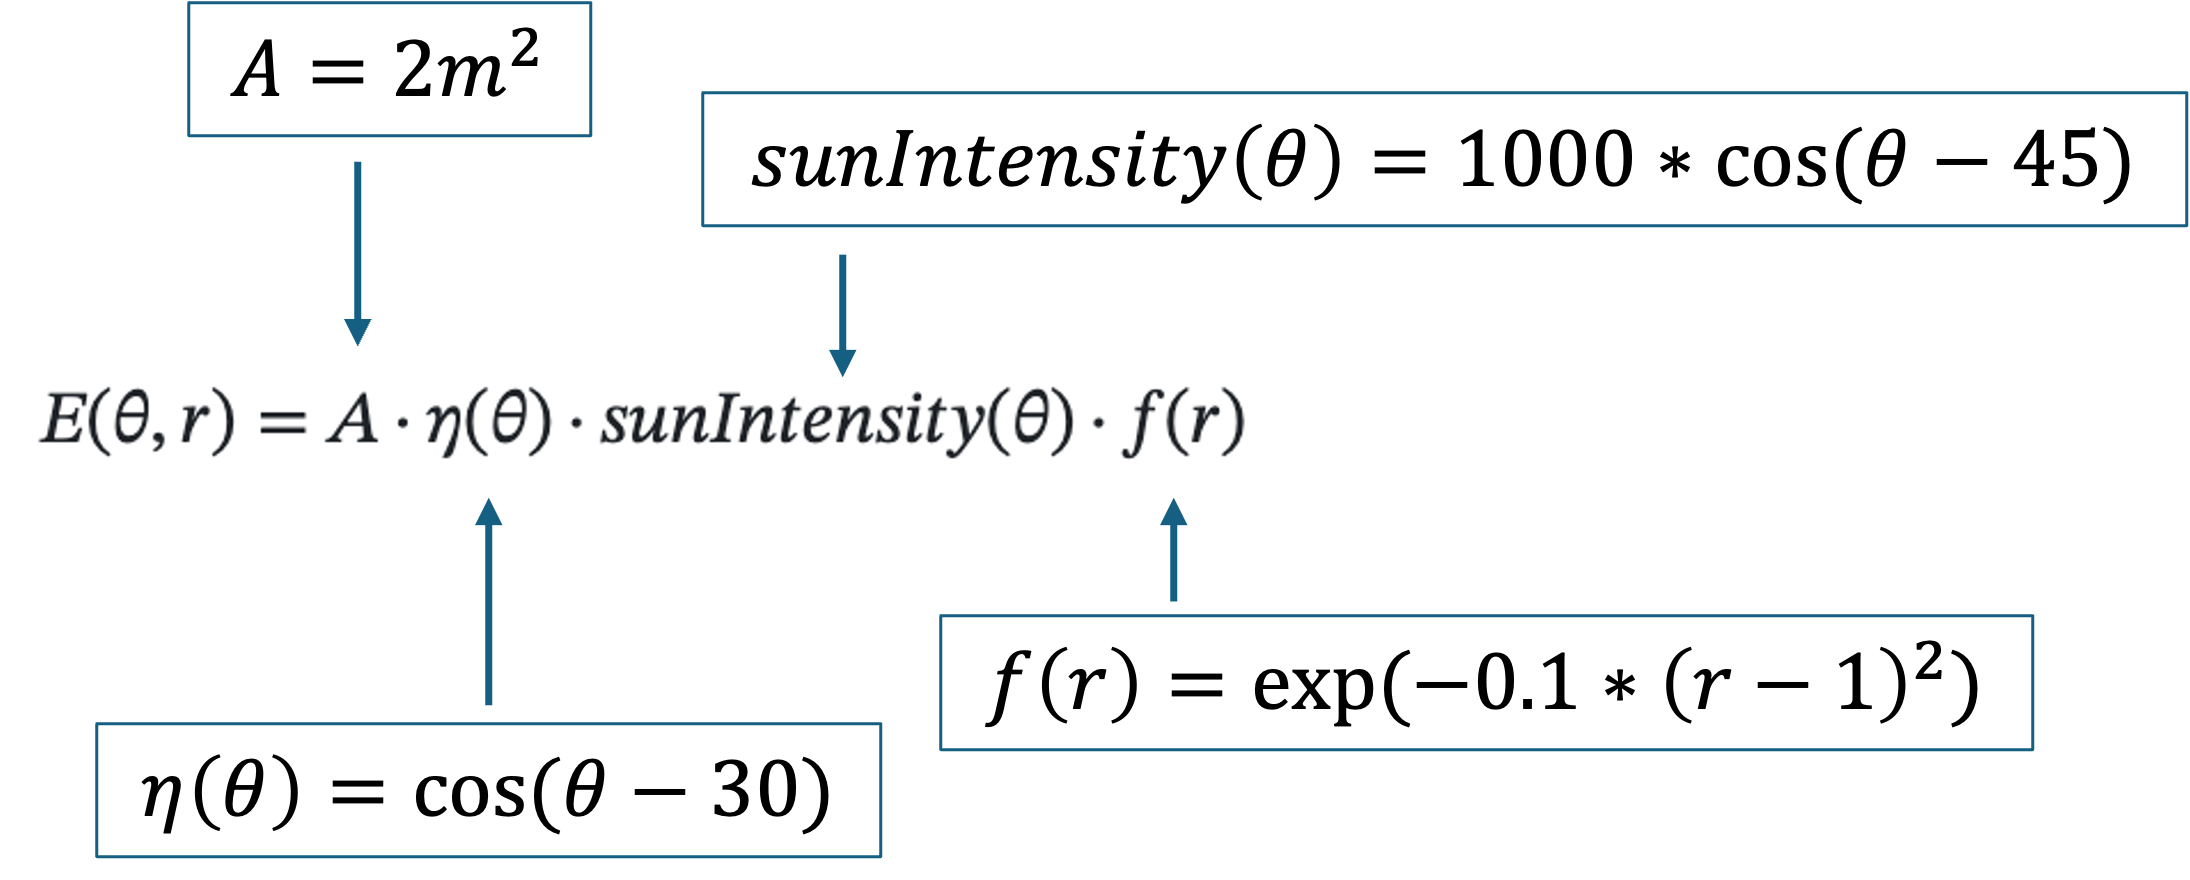

% Defining variable A (solar panel area in m^2)
A = 2.0;

% Define the optimization variables we can change in the problem
% These are the values MATLAB will try to optimize:
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4
theta = optimvar('theta', Lowerbound = 0, Upperbound =  90);
r = optimvar('r', Lowerbound = 0.5, Upperbound = 4);

% Define nu (efficiency function based on tilt angle (theta))
eta = cos((theta - 30) * pi/180);

% Define sunIntensity (sunlight variation based on the tilt angle (theta))
sunIntensity = 1000 * cos((theta - 45) * pi/180);

% Define fr (shape efficiency factor based on aspect ratio (r))
fr = exp(-0.1 * (r-1).^2);

%Calculate E (total energy output)
E = A * eta * sunIntensity * fr;

## Task 2: Implement the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. We referred to this MATLAB [doc page](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html).

% Create the optimization problem
prob = optimproblem("Description", "Maximum Energy in Solar Panel");


% Turn our energy function into an optimization problem MATLAB can work
% with.
E = A * eta * sunIntensity * fr;

% Tell MATLAB what we want to maximize
% We set our energy formula as the "objective" of the problem
% (this is what we want the solver to maximize)
prob.Objective = E;
prob.ObjectiveSense = "maximize";

% Give MATLAB a starting point to begin the search:
% Start searching from a tilt angle of 0 degrees
x0.theta = 0;
% Start searching from an aspect ratio of 0.5
x0.r = 0.5;

% Now solve the problem. Store the solution (the optimal value of theta and r) in variable sol. Begin the search at x0.
sol = solve(prob, x0);


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


maxEnergy = evaluate(E, sol);


## Task 3: Output the Results

Use the appropriate plotting function to plot E(θ, r) and visualize the energy surface. Print the optimal tilt angle and aspect ratio, and corresponding energy output.

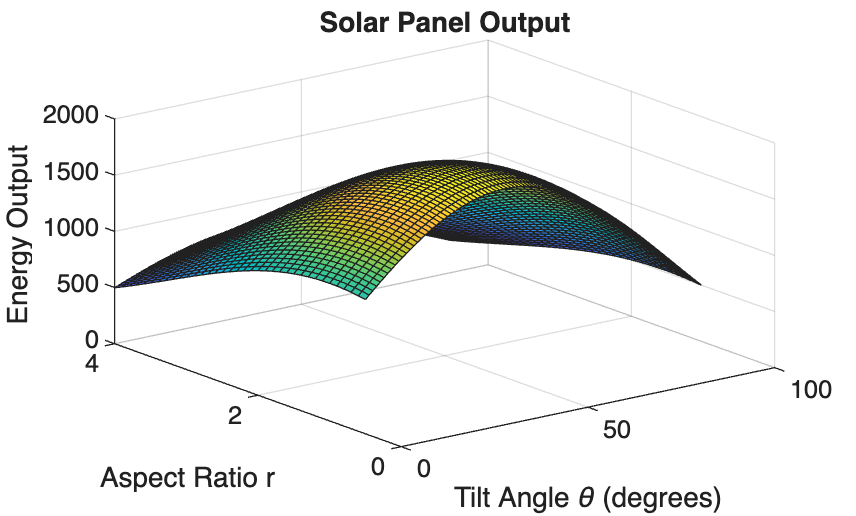

% Make a bunch of points for the x and y axis meshgrid
% The step for the angle is 1, the step for ratio is 0.1
% Hint: keep theta and r within the constraints specified in the problem
thetaValues = 0:1:90;
rValues = 0.5:0.1:4;
[T, R] = meshgrid(thetaValues, rValues);

% Calculate energy for every point on the meshgrid using element-wise operations
etaPlot = cos((T - 30) * pi/180);
sunIntensityPlot = 1000 * cos((T - 45) * pi/180);
frPlot = exp(-0.1 * (R - 1).^2);
EPlot = A .* etaPlot .* sunIntensityPlot .* frPlot;
% Draw the 3d graph using the "surf" function
surf(T, R, EPlot);

% Label everything on the surf plot (title, axes, etc)
title("Solar Panel Output")
xlabel('Tilt Angle \theta (degrees)')
ylabel('Aspect Ratio r')
zlabel('Energy Output ')


% Print the optimal tilt angle and aspect ratio, and corresponding
% energy output to the command window
fprintf('Optimal tilt angle = %.2f degrees \n', sol.theta); 

Optimal tilt angle = 37.50 degrees 


fprintf('Optimal aspect ratio = %.2f\n', sol.r); 

Optimal aspect ratio = 1.00


fprintf('Optimal Max Energy = %.2f units \n', maxEnergy); 

Optimal Max Energy = 1965.93 units 


## Interpretation of Results

**Summarize your findings by interpreting their physical/engineering meaning:**

The maximum energy is generated by the solar panel when the tilt angle is 37.5 degrees and optimal aspect ratio is 1. 

**What are some limitations of your work?**

In the equation for efficiency function based on tilt angle, we have defined that the latitude of installation location is 30 degrees through the equation cos(θ-30). In the real world, latitude is not fixed and it varies with the location and season. 

Similarly, for the equation for the sunlight intensity, we have defined the sun’s position as 45 degrees elevation through the equation 1000* cos(θ-45). In the real world, the sun's position changes throughout the day and throughout the year.

**What are practical next steps?**

Next steps of the problem would be researching the specific latitude based on the given location and reproducing the equation. We could also take the sun’s position into consideration in the sunlight intensity equation. 

Additionally, we would alter the maximum area of the solar panel based on the provided resources.